# ME441-001 Final Project

## Daniel Waggner + Corbin Strycker

Problem DFN:

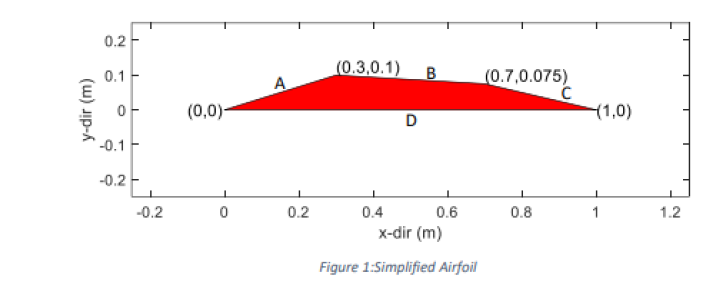

Initial CMDs

clear; 
clc;
close all;
format short;

Data

% Angle of Attack
alpha = 10; 
% Requested Mach Number(s)
M1Init = 3.0; 

Variable DFNs

% Flow Vector
flowVectorMag = 0.35;
flowVectorPosx = -1 * flowVectorMag * cosd(alpha);
flowVectorPosy = flowVectorMag * sind(alpha); 

xvalstop = [flowVectorPosx, 0, 0.3, 0.7, 1.0];
yvalstop = [flowVectorPosy, 0, 0.1, 0.075, 0];

xvalsbottom = [flowVectorPosx, 0, 1.0];
yvalsbottom = [flowVectorPosy, 0, 0];

Assumptions:

    1. Acting Fluid is Air modeled as a callorically perfect gas

    2. Frictionless Flow (Inviscid)

    3. Fluid is Air @ STP

gamma = 1.4;
T_flow = 293; % k
P_flow = 101325; % Pa
rho_flow = 1.21; % kg/m^3

Plotting Airfoil

hold on;
fill(xvalstop(2:length(xvalstop)),...
    yvalstop(2:length(yvalstop)), 'r');
xlim([-0.4 1.4]);
ylim([-0.4, 0.4]);
xticks(-0.2:0.2:1.2);

title("Asymmetric Airfoil Diagram");
xlabel("X-direction (m)");
ylabel("Y-direction (m)");
grid on; 
box on;

%Plotting Velocity Vector Line
plot([flowVectorPosx, 0], [flowVectorPosy, 0], 'b');

%Velocity Vector Labeling 
velStr1 = "AirFlow:";
velStr2 = append("M = ", num2str(round(M1Init,2)));
velStr3 = append("\alpha = ",...
    num2str(round(alpha, 2)));
lableString = append(velStr1, velStr2);
text(-0.35, -0.2,...
    [velStr1, velStr2, velStr3]);


Evaluating Flow Stuff

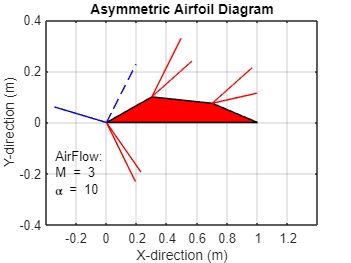


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


%Evaluating airfoil as 2 halves
%   j = 1: top half
%   j = 2: bottom half
for j = 1:2
    %Resetting the Current Mach No. back to the
    %   oncoming flow's velocity
    %   + properties
    M1 = M1Init;
    P01 = P_flow;
    T01 = T_flow;
    Rho01 = rho_flow;

    %Handling Top vs Bottom Cases
    if j == 1
       valueInterestLength = length(xvalstop); 
    else
       valueInterestLength = length(xvalsbottom);
    end
    %Running Flow Analyses
    for i = 3:valueInterestLength
        %DFN relative vectors
        %   i.e. vectors that overlap the
        %   DFN's airfoil's edges
        if j == 1 % top half of foil points
            %x-values
            x1 = xvalstop(i-2);
            x2 = xvalstop(i-1);
            x3 = xvalstop(i);
            %y-values
            y1 = yvalstop(i-2);
            y2 = yvalstop(i-1);
            y3 = yvalstop(i);
        else % bottom half of foil points
            %x-values
            x1 = xvalsbottom(i-2);
            x2 = xvalsbottom(i-1);
            x3 = xvalsbottom(i);
            %y-values
            y1 = yvalsbottom(i-2);
            y2 = yvalsbottom(i-1);
            y3 = yvalsbottom(i);
        end
        %Handle Origin
        if x2==0 && y2==0
            linfit = polyfit([x1, x2], [y1, y2], 1);

            vec1coords = [x2, 0.2;...
                y2, linfit(1)*0.2 + linfit(2)];
            vec2coords = [x2, x3;...
                y2, y3];
            vec3coords = [0.2, x3;...
                linfit(1)*0.2 + linfit(2), y3]; 
        else
            vec1coords = [x2, 2*x2; y2, 2*y2];
            vec2coords = [x2, x3; y2, y3];
            vec3coords = [2*x2, x3; 2*y2, y3]; 
        end
        
        %Prepping Law of Cosines
        vec1length = sqrt((vec1coords(1,2) ...
            - vec1coords(1,1))^2 + (vec1coords(2,2)...
            - vec1coords(2,1))^2);
        
        vec2length = sqrt((vec2coords(1,2) ...
            - vec2coords(1,1))^2 + (vec2coords(2,2)...
            - vec2coords(2,1))^2);
    
        vec3length = sqrt((vec3coords(1,2) ...
            - vec3coords(1,1))^2 + (vec3coords(2,2)... 
            - vec3coords(2,1))^2);
    
        vec1 = [vec1coords(1,2) - vec1coords(1,1), ...
            vec1coords(2,2) - vec1coords(2,1)];
    
        vec2 = [vec2coords(1,2) - vec2coords(1,1), ...
            vec2coords(2,2) - vec2coords(2,1)];
    
        vec3 = [vec3coords(1,2) - vec3coords(1,1), ...
            vec3coords(2,2) - vec3coords(2,1)];
        
        %Compute Turning Angles via Vectors
        %   Law of Cosines
        theta = acosd((vec1length^2 + vec2length^2 ...
            - vec3length^2) / (2 * vec1length ...
            * vec2length));     % degrees
        %   Evaluating Direction
        %       (-) Clockwise:
        %           Expansion Fan
        %       (+) Counter-Clockwise:
        %           Oblique Shockwave
        
        if j == 2 % handling bottom side case
                    %   via flipping angle along 
                    %   x-axis
            thetaDirection = -1 * AngleIn2D(vec1,...
                vec2);
                                        % radians
        else
            thetaDirection = AngleIn2D(vec1, vec2);
                                        % radians
        end
        
        %Handling Cases
        if thetaDirection < 0 % Expansion Fan

            [M2, nu1, mu1] = flowprandtlmeyer(...
                gamma, M1, 'mach');
            nu2 = nu1 - theta;
            [M1, nu2, mu2] = flowprandtlmeyer(...
                gamma, abs(nu2), 'nu');

            %handling bottom half of foil
            %   via flipping angle along
            %   x-axis
            if j == 2
                nu1 = nu1 - 90;
                nu2 = nu2 - 90;
            end
            
            %Plotting Expansion Fans
            plot([x2, x2+.3*cosd(nu1)],[y2, ...
                y2+.3*sind(nu1)], 'r');
            plot([x2, x2+.3*cosd(nu2)],[y2, ...
                y2+.3*sind(nu2)], 'r');
    
        elseif thetaDirection > 0 % Oblique Shock
            beta = InvertTBM(theta, M1, gamma, 1);

            %Oblique Shock Properties
            [T2, T02, P2, P02, Rho2, M2] = ...
                obliqueShocker(theta, beta,M1,gamma,T01, ...
                P01,Rho01);
            
            if j == 2
                beta = beta - 90;
            end

            %handling bottom half of foil
            %   via flipping angle along
            %   x-axis
            plot([x2, x2+.3*cosd(beta)], ...
                [y2, y2+.3*sind(beta)], 'b--');
            
        else    
            %Case Where an Inputted Airfoil 
            %   Has Points Defining a Straight Edge
            continue;
        end
    end
end


%   salesartillery.com/fs/top-100-aerospace-companies
%   usajobs